# Spatial Query Example

This example uses a spatial query to obtain metadata.

## Step1: Select Location

Select the location for the spatial query.  This location value is used in the spatial query.

Use the sliders to select a latitude and longitude location or type in the value.  

lat = 40.015;
lon = -105.2705;

Plot the location on a map using geobubble.

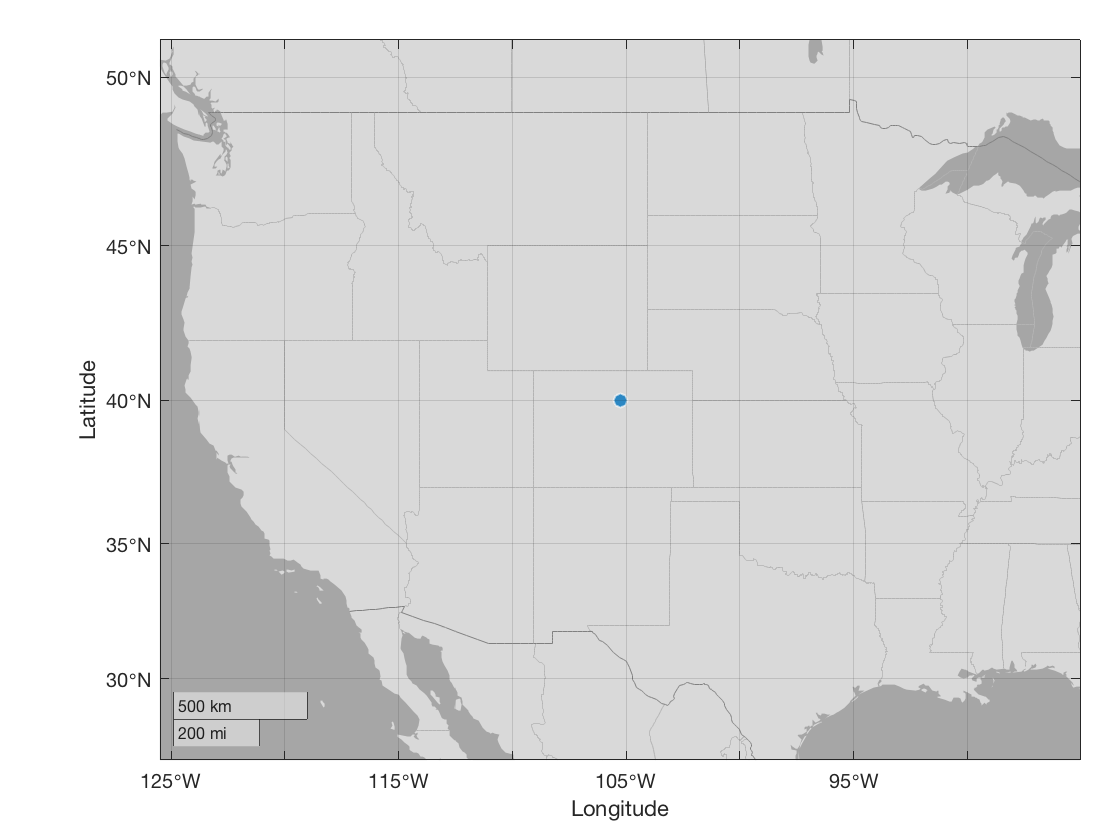

gb = geobubble(lat,lon);

## Step 2: Create a GeoJSON FeatureCollection

 Convert the latitude/longitude location to a GeoJSON FeatureCollection character array in order to create a query.

json = ...
    ['{"type": "FeatureCollection","features": ' ...
    '[{"type": "Feature","geometry": ', ...
     '{"type": "Point","coordinates": [lon, lat]}}]}'];
 json = replace(json,'lon',num2str(lon));
 json = replace(json,'lat',num2str(lat));
 feature_collection_str = json;

## Step 3: Set Search Type

 Set type of search for spatial search.

 search_type = "spatial/search/object";

## Step 4: Set Request URL

 Set the request domain URL for the geodex web service.

 % Set core domain name for request URL
domain_url = "http://geodex.org/api/v1/";

% Create request URL
request_url = domain_url + search_type;

## Step 5: Create URL Parameters

Create a cell array to hold URL submission parameters.

params = {'geowithin', feature_collection_str};

## Step 6:  Call RESTful Web Service

Make call to the geodex RESTful web service using webread.

options = weboptions('ContentType','json');
data = webread(request_url,params{:},options);
features = data.features;

## Step 7: Explore results.

number_of_results = length(features);
first_result = features(1);

url = first_result.properties.URL;
coordinates = first_result.geometry.coordinates;
scoordinates = sprintf('%s\n',join(string(coordinates)));
output = string( ...
    "Number of Results = " + string(number_of_results) + newline + ...
    "URL of First Result = " + url + newline + ...
    "Coordinates of First Result" + newline + ...
    scoordinates);
fprintf('%s\n',output)

Number of Results = 531
URL of First Result = http://get.iedadata.org/doi/310660
Coordinates of First Result
-129.4934 5.049939
-79.17673 5.049939
-79.17673 48.48632
-129.4934 48.48632
-129.4934 5.049939



Convert data to a table that contains the latitdue and longitude location of the center of the data if a Polygon type

and include the URL and geometry type.

features = data.features;
datalat = zeros(length(features),1);
datalon = datalat;
for k = 1:length(features)
    coordinates = features(k).geometry.coordinates;
    if length(coordinates) == 2
        datalon(k) = coordinates(1);
        datalat(k) = coordinates(2);
    else
        datalon(k) = mean(coordinates(:,:,1));
        datalat(k) = mean(coordinates(:,:,2));
    end
end

geometry = [features.geometry];
type = categorical({geometry.type})';
props = [features.properties];
url = {props.URL}';
t = table(datalat,datalon,type,url);


Plot the locations of the data. Hover the mouse over a point to see the datatip.

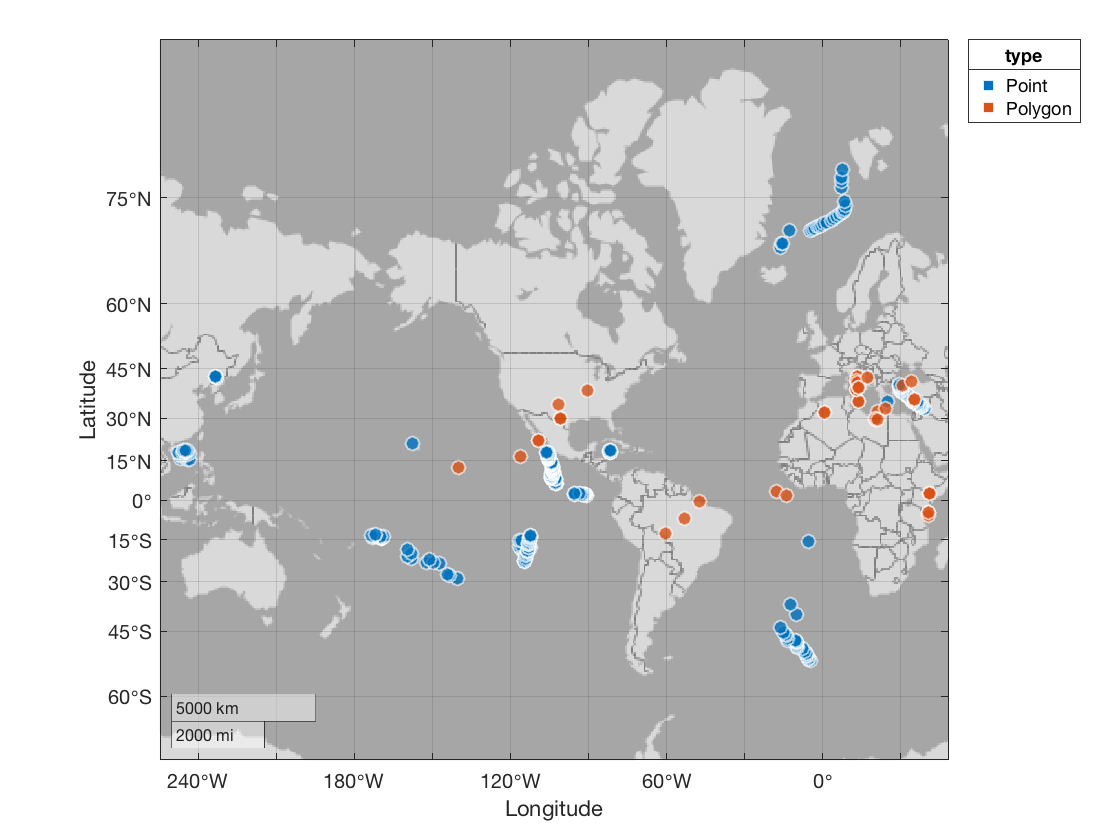

figure
geobubble(t,'datalat','datalon','ColorVariable','type');

## Step 8: Query for Metadata

Now use the RESTful web service to query for metadata about the first dataset.

index = 1;
dataurl = url{1};
search_type = "graph/details";
request_url = domain_url + search_type;
params = {'r', dataurl};
data = webread(request_url, params{:}, options);

## Step 9: Examine Metadata

output = string( ...
    "Dataset Webpage URL = " + data.URL + newline + ...
    "Name = " + data.Name + newline + ...
    "Alternate Name = " + data.Aname + newline + ...
    "URI = " + data.S + newline + ...
    "Keywords = " + data.Keywords + newline + ...
    "Description = " + data.Description + newline + ...
    "Citation = " + data.Citation + newline + ...
    "Date Published = " + data.Datepublished + newline + ...
    "License = " + data.License + newline + ...
    "Dataset Download Link = " + data.Curl);
fprintf('%s\n',output)

Dataset Webpage URL = http://get.iedadata.org/doi/310660
Name = Processed ship-based Navigation Data acquired during the Robert D. Conrad expedition RC1011 (1966)
Alternate Name = 
URI = DOI:10.1594/IEDA/310660
Keywords = Navigation:Primary
Description = Abstract: This data set was acquired with a ship-based Navigation system during Robert D. Conrad expedition RC1011 conducted in 1966 (Chief Scientist: Dr. Charles Fray). These data files are of Text File (ASCII) format and include Navigation data and were processed after data collection.
Citation = Fray, Charles (2009), Processed ship-based Navigation Data acquired during the Robert D. Conrad expedition RC1011 (1966). Interdisciplinary Earth Data Alliance (IEDA). doi:10.1594/IEDA/310660
Date Published = 2009
License = Creative Commons Attribution-NonCommercial-Share Alike 3.0 United States [CC BY-NC-SA 3.0]
Dataset Download Link = 
